********************
* SensorDataReader started on 192.168.31.5:3400
********************
Connection accepted from 192.168.31.116:41126


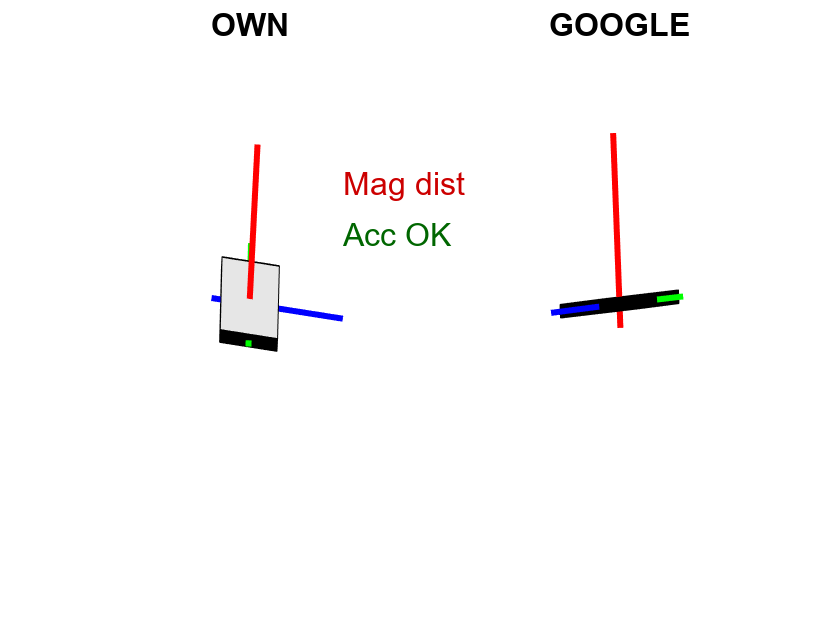

[xhat, meas] = filterTemplate();

# Task2

%filter and away from disturbance

[mu_acc, Sigma_acc] = approxGaussianTransform(meas.acc(:, ~any(isnan(meas.acc), 1)))

mu_acc =    -0.0698
    0.1296
    9.8607


Sigma_acc = 1.0e-03 *

    0.0538    0.0005   -0.0144
    0.0005    0.0416    0.0044
   -0.0144    0.0044    0.3620


[mu_gyr, Sigma_gyr] = approxGaussianTransform(meas.gyr(:, ~any(isnan(meas.gyr), 1)))

mu_gyr = 1.0e-03 *

   -0.0594
   -0.1348
    0.0545


Sigma_gyr = 1.0e-05 *

    0.0526    0.0675   -0.0118
    0.0675    0.2002   -0.0277
   -0.0118   -0.0277    0.0308


[mu_mag, Sigma_mag] = approxGaussianTransform(meas.mag(:, ~any(isnan(meas.mag), 1)))

mu_mag =    -8.9078
  -34.8681
   -6.2037


Sigma_mag =     0.0812   -0.0051    0.0049
   -0.0051    0.1222   -0.0141
    0.0049   -0.0141    0.0962


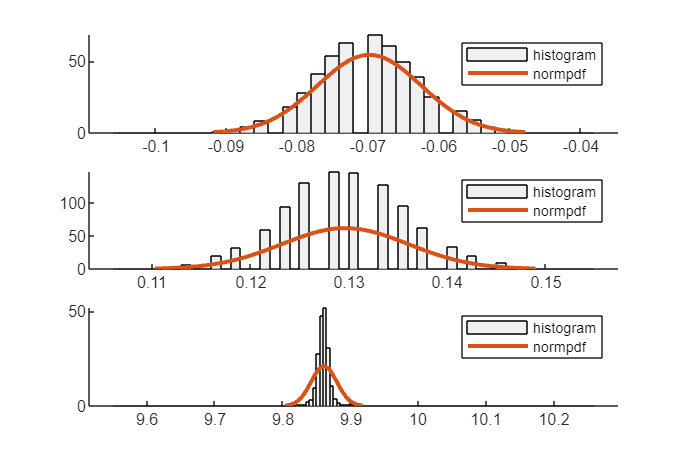

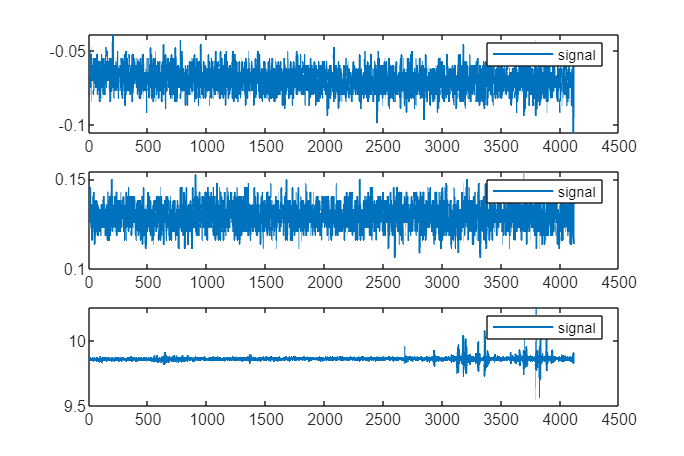

t1=meas.acc(:, ~any(isnan(meas.acc),1));
t2=meas.gyr(:, ~any(isnan(meas.gyr),1));
t3=meas.mag(:, ~any(isnan(meas.mag),1));
plothistogram(t1,mu_acc,Sigma_acc,t1);

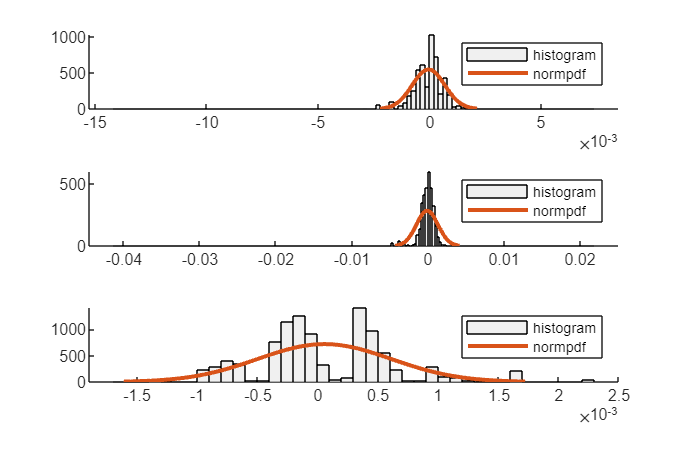

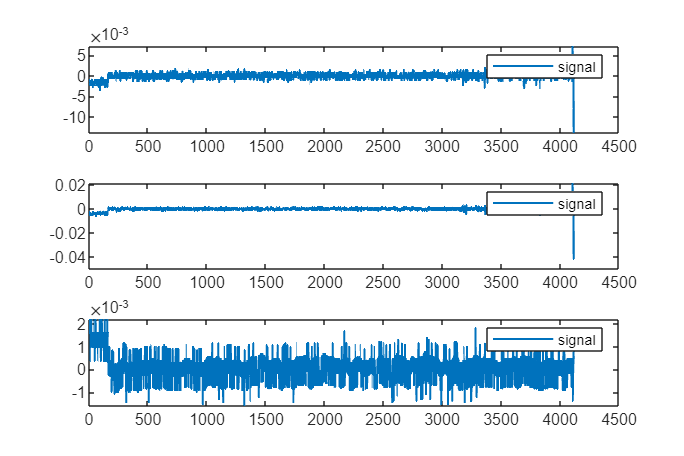

plothistogram(t2,mu_gyr,Sigma_gyr,t2);

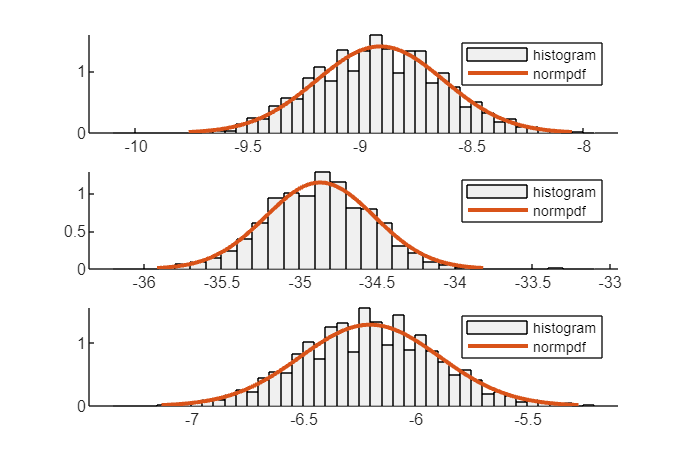

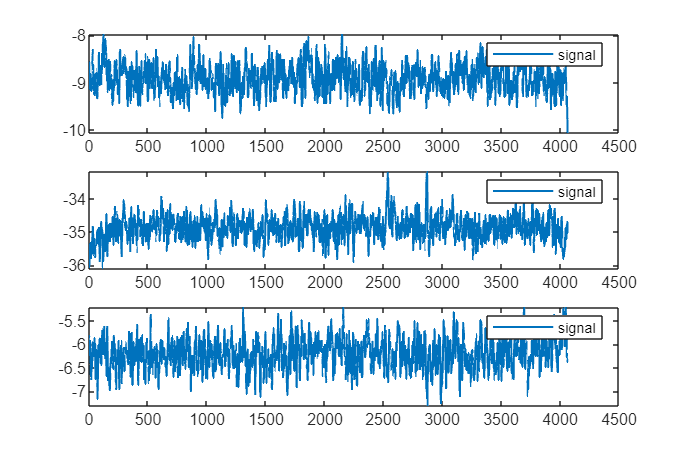

plothistogram(t3,mu_mag,Sigma_mag,t3);

# Task 3

%see note

# Task 4

# task 5

********************
* SensorDataReader started on 192.168.31.5:3400
********************
Connection accepted from 192.168.31.116:41964


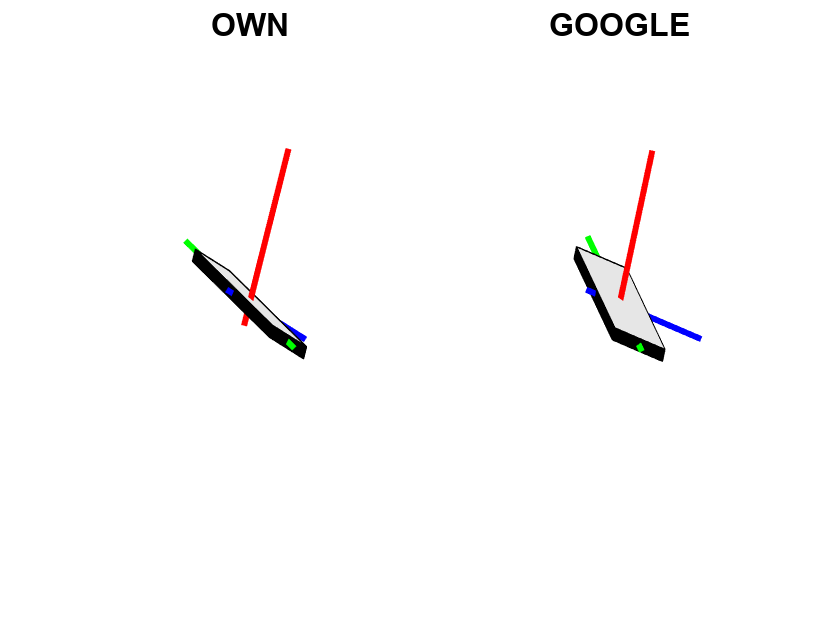

mu_acc1 =    NaN
   NaN
   NaN


Sigma_acc1 =      0     0     0
     0     0     0
     0     0     0


mu_gyr1 =    NaN
   NaN
   NaN


Sigma_gyr1 =      0     0     0
     0     0     0
     0     0     0


mu_mag1 =    NaN
   NaN
   NaN


Sigma_mag1 =      0     0     0
     0     0     0
     0     0     0


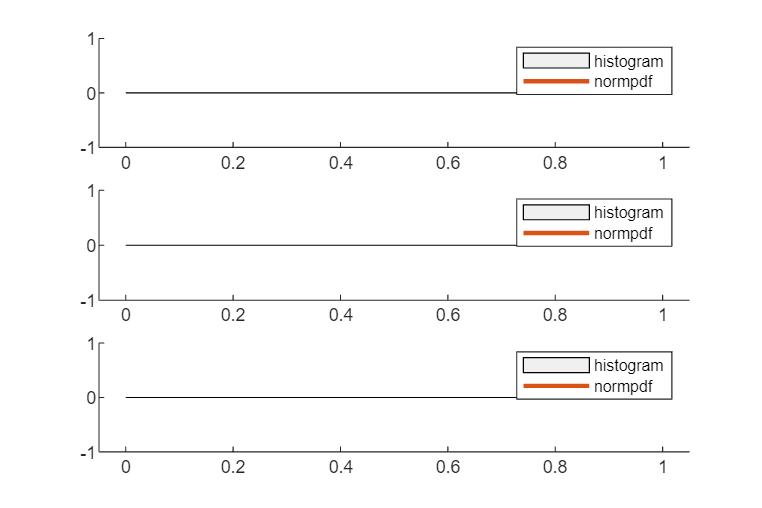

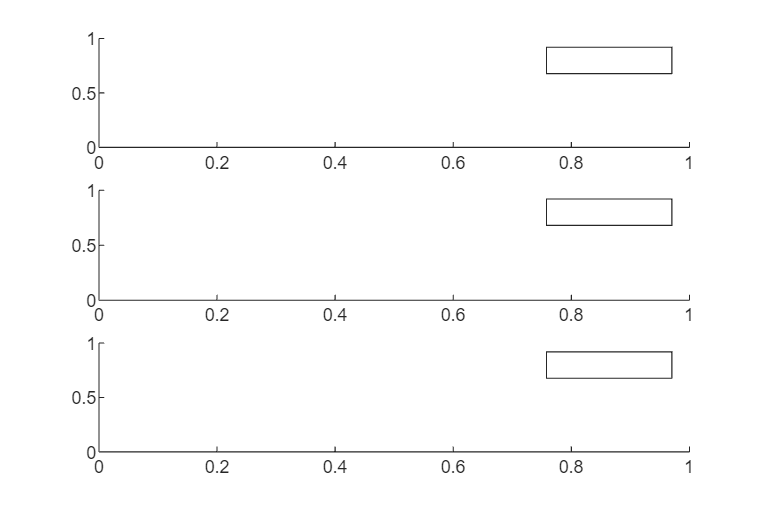

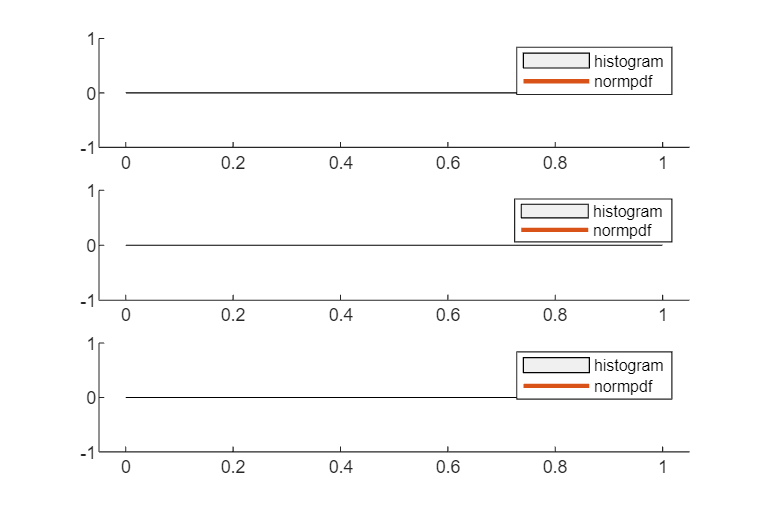

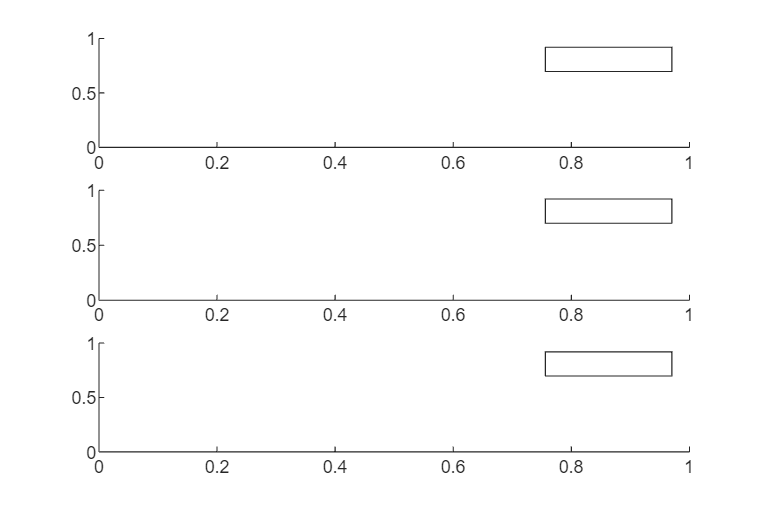

[xhat1, meas1] = filterTemplate_new();